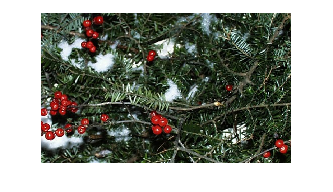

clear all
close all
clc

cover_image = double(imread('greens.jpg'));
figure, imshow(cover_image / 255);

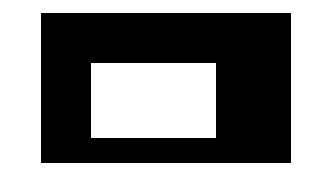

y = cover_image;
secret_image = zeros(300, 500);
secret_image(100:250, 100:350) = 1;
figure, imshow(secret_image)

save m.dat secret_image -ascii

% Water marking
%DCT of RGB of cover image
ci_r = cover_image(:,:,1);
ci_g = cover_image(:,:,2);
ci_b = cover_image(:,:,3);

dx1 = dct2(ci_r);  dx11 = dx1 ;
dx2 = dct2(ci_g);  dx22 = dx1 ;
dx3 = dct2(ci_b);  dx33 = dx1 ;

load m.dat  
% binary_mask_for_watermarking
g = 10; % Coefficient of watermark's strength
[rm, cm] = size(m);
%Adding the secret Image rows and columns into cover Image's All DCT coefficients  
dx1(1:rm, 1:cm) = dx1(1:rm, 1:cm) + g * m;
dx2(1:rm, 1:cm) = dx2(1:rm, 1:cm) + g * m;
dx3(1:rm, 1:cm) = dx3(1:rm, 1:cm) + g * m;
% figure, imshow(dx1);
% figure, imshow(dx2);
% figure, imshow(dx3);

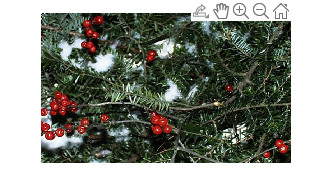

%Inverse DCT for the Embedded Image creation
y1 = idct2 (dx1);
y2 = idct2 (dx2);
y3 = idct2 (dx3);
y(:,:,1) = y1;
y(:,:,2) = y2;
y(:,:,3) = y3;

% figure, imshow(y1);
% figure, imshow(y2);
% figure, imshow(y3);
% figure, imshow(y);
figure, imshow(y/255)

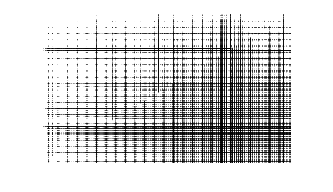

figure , imshow(abs (y-cover_image)*100) 

z = y ;
[r,c,s] = size(z) ;

% De-watermarkig
% Clean image (known mask)
y = z;
dy1 = dct2 (y (:,:,1));
dy2 = dct2 (y(:,:,2));
dy3 = dct2 (y (:,:,3));

dy1 (1:rm, 1: cm) = dy1 (1:rm, 1: cm) - g* m;
dy2 (1:rm, 1: cm)= dy2 (1:rm, 1: cm) - g* m;
dy3 (1:rm, 1: cm) = dy3 (1:rm, 1: cm) - g* m;

y11 = idct2 (dy1);
y22 = idct2 (dy2);
y33 = idct2 (dy3);

yy (:,:,1) = y11;
yy (:,:,2) = y22;
yy (:,:,3) = y33;
figure ; imshow (yy/255)

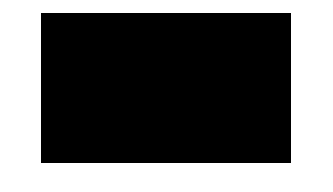

figure; imshow (abs (yy-cover_image) *10000)